Alfredo Robledano Abasolo Grupo 1ºB

# Ejercicio Tema 1

#### a) (7 p) Escribe un script en MATLAB en el que calcules el número de condición de la función:


$$f\left(x\right)=\;\frac{\sin \left(x\right)}{\cos \left(x\right)+1}\;\mathrm{para}\;x_0 =1\ldotp 0001\pi$$


Para este ejercicio haremos uso de la librería simbólica de matlab.

Primero introducimos los datos.

Declaramos la función f(x) definiendo la variable independiente x como simbólica y el punto que queremos estudiar.

syms x
f = sin(x) / (1+cos(x))

$$f = \frac{\sin\left(x\right)}{\cos\left(x\right)+1}$$

x0 = 1.0001*pi

x0 = 3.1419

Calculamos la primera derivada con la función diff()

derivada = diff(f)

$$derivada = \frac{{\sin\left(x\right)}^{2}}{{\left(\cos\left(x\right)+1\right)}^{2}}+\frac{\cos\left(x\right)}{\cos\left(x\right)+1}$$

Obtenemos la expresión del número de condición que tiene la forma:

nº de condición = $\left|\frac{f^{\prime } \left(x\right)}{f\left(x\right)}\right|\;x$

n_condicion = abs(derivada / f) * x

$$n\_condicion = \frac{x\,\left|\left(\cos\left(x\right)+1\right)\,\left(\frac{{\sin\left(x\right)}^{2}}{{\left(\cos\left(x\right)+1\right)}^{2}}+\frac{\cos\left(x\right)}{\cos\left(x\right)+1}\right)\right|}{\left|\sin\left(x\right)\right|}$$

Finalmente evaluamos la expresión en el punto dato del ejercicio para obtener su valor.

n = eval(subs(n_condicion, x0))

n = 1.0001e+04

fprintf('El número de condición en x0 es %.f.', n)

El número de condición en x0 es 10001.

#### b) (3 p) Dibuja la gráfica de f(x) en un entorno de x0. Explica el número de condición obtenido a la vista de la gráfica

Para graficar la función haremos uso de la función fplot() a la cual podemos pasar la función simbólica utilizada anteriormente, y un intervalo entorno de x0.

fplot(f, [x0-1, x0+1], LineWidth=0.6)

Matlab nos marca que hay una asíntota vertical en x=$\pi$.

La dibujamos:

hold on
xline(pi, LineWidth=0.5, Color='red', LineStyle='--')
hold off

Finalmente añadimos etiquetas y leyenda.

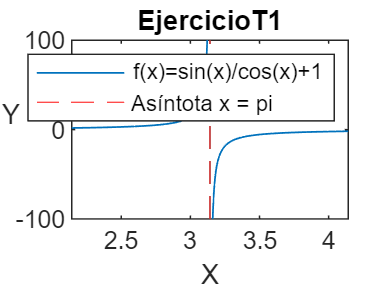

title("EjercicioT1") 
xlabel('X')
ylabel('Y', Rotation=0)
legend('f(x)=sin(x)/{cos(x)+1}', 'Asíntota x = pi')

Observamos que obtenemos un número de condición muy alto debido a que cerca del punto pedido la función posee una asíntota vertical.